

% Carregar saída do transdutor
load('V_transdutor.mat', 'V_transdutor', 't', 'Fs');

% Parâmetros do subtrator
V_ref = 1; % Tensão de referência
R1 = 10e3;   % 10 kOhm
R2 = 5e3;   % 10 kOhm

% Aplicar subtrator com ganho (R2/R1)
V_subtrator = (R2/R1) * (V_transdutor + V_ref);


% Salvar saída
save('V_subtrator.mat', 'V_subtrator', 't', 'Fs');
disp('Saída do subtrator salva em dados/V_subtrator.mat');

Saída do subtrator salva em dados/V_subtrator.mat


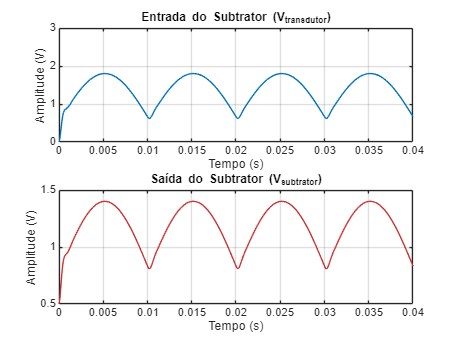


% Plotagem
figure;
subplot(2,1,1);
plot(t, V_transdutor);
ylim([0 3]);
title('Entrada do Subtrator (V_{transdutor})');
xlabel('Tempo (s)'); ylabel('Amplitude (V)'); grid on;

subplot(2,1,2);
plot(t, V_subtrator, 'Color', [0.8 0.2 0.2]);
%ylim([0 3]);
title('Saída do Subtrator (V_{subtrator})');
xlabel('Tempo (s)'); ylabel('Amplitude (V)'); grid on;